clc;
clear;
%阴极铝箔
t_Al_1=[0 97 141	190	237	282	327	371	414	458	505	547	594	633	676	717	758	797	836	877	919];
t_Al_2=[0	104	153	201	251	296	343	388	435	479	523	566	609	654	708	741	782	828	865	906	949];
t_Al_3=[0	82	139	190	238	284	331	378	421	469	511	556	599	641	684	726	768	807	846	889	929];
u_Al_1=[2.9	3.6	4	4.4	4.8	5.2	5.5	5.9	6.3	6.6	7.1	7.4	7.8	8.1	8.5	8.9	9.2	9.6	9.9	10.3	10.7];
u_Al_2=[2.9	3.7	4	4.4	4.8	5.2	5.6	6	6.4	6.7	7.1	7.5	7.9	8.3	8.6	9	9.4	9.8	10.1	10.5	10.9];
u_Al_3=[2.9	3.4	3.9	4.3	4.7	5.1	5.4	5.8	6.2	6.5	6.9	7.3	7.7	8	8.4	8.7	9.1	9.4	9.8	10.1	10.5];
t_Al=(t_Al_1+t_Al_2+t_Al_3)/3

t_Al =          0   94.3333  144.3333  193.6667  242.0000  287.3333  333.6667  379.0000  423.3333  468.6667  513.0000  556.3333  600.6667  642.6667  689.3333  728.0000  769.3333  810.6667  849.0000  890.6667  932.3333


u_Al=(u_Al_1+u_Al_2+u_Al_3)/3

u_Al =     2.9000    3.5667    3.9667    4.3667    4.7667    5.1667    5.5000    5.9000    6.3000    6.6000    7.0333    7.4000    7.8000    8.1333    8.5000    8.8667    9.2333    9.6000    9.9333   10.3000   10.7000


y=0:50:1000

y =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000



%阴极钛箔
t_Ti_1=[0	72	122	174	221	269	320	368	416	466	485	559	610	654	701	747	793	827	880	930	976];
t_Ti_2=[0	53	87	131	176	222	268	312	356	401	450	495	544	590	641	684	731	779	824	874	921];
t_Ti_3=[0	56	112	169	224	274	323	369	412	456	500	544	589	634	674	730	777	826	875	927	971];
u_Ti_1=[2.6	3.1	3.4	3.9	4.3	4.7	5.1	5.5	5.9	6.3	6.7	7.1	7.5	8	8.3	8.7	9.2	9.6	10	10.3	10.9];
u_Ti_2=[2.3	2.7	2.9	3.3	3.6	4	4.4	4.7	5.1	5.5	5.9	6.3	6.7	7.1	7.5	7.9	8.3	8.7	9.1	9.6	10.1];
u_Ti_3=[2.2	2.7	3.1	3.6	4	4.4	4.8	5.2	5.6	5.9	6.3	6.7	7.1	7.5	7.8	8.3	8.7	9.2	9.6	10.1	10.5];
t_Ti=(t_Ti_1+t_Ti_2+t_Ti_3)/3

t_Ti =          0   60.3333  107.0000  158.0000  207.0000  255.0000  303.6667  349.6667  394.6667  441.0000  478.3333  532.6667  581.0000  626.0000  672.0000  720.3333  767.0000  810.6667  859.6667  910.3333  956.0000


u_Ti=(u_Ti_1+u_Ti_2+u_Ti_3)/3

u_Ti =     2.3667    2.8333    3.1333    3.6000    3.9667    4.3667    4.7667    5.1333    5.5333    5.9000    6.3000    6.7000    7.1000    7.5333    7.8667    8.3000    8.7333    9.1667    9.5667   10.0000   10.5000


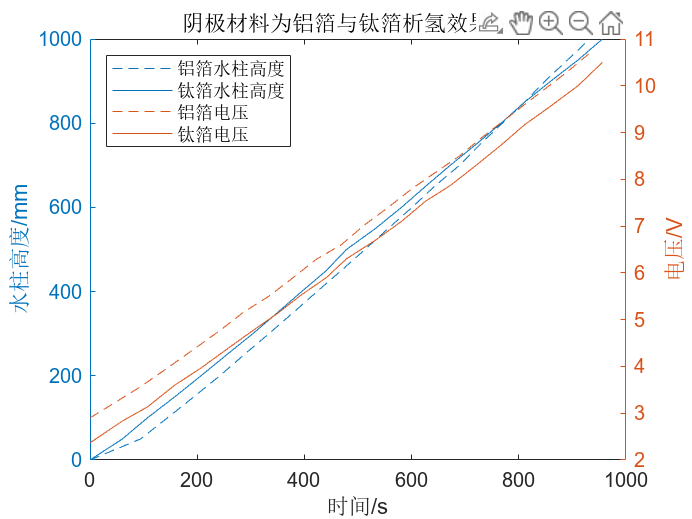


%折线图
figure;
yyaxis left;
plot(t_Al,y,'--',t_Ti,y,'-');
ylabel('水柱高度/mm');
yyaxis right;
plot(t_Al,u_Al,'--',t_Ti,u_Ti,'-');
xlabel('时间/s');
ylabel('电压/V');
legend('铝箔水柱高度','钛箔水柱高度','铝箔电压','钛箔电压','location','northwest')
title('阴极材料为铝箔与钛箔析氢效果对比');

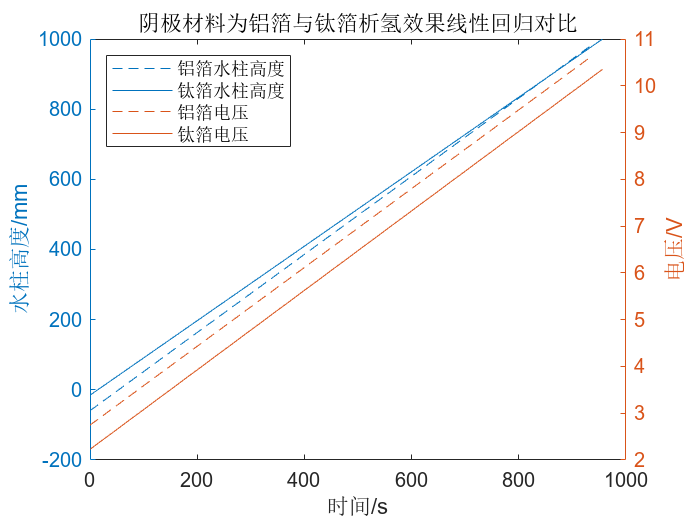


%线性拟合
figure;
yyaxis left;
pt_Al=polyfit(t_Al,y,1);
ft_Al=polyval(pt_Al,t_Al);
pt_Ti=polyfit(t_Ti,y,1);
ft_Ti=polyval(pt_Ti,t_Ti);
plot(t_Al,ft_Al,'--',t_Ti,ft_Ti,'-');
ylabel('水柱高度/mm');
yyaxis right;
pu_Al=polyfit(t_Al,u_Al,1);
fu_Al=polyval(pu_Al,t_Al);
pu_Ti=polyfit(t_Ti,u_Ti,1);
fu_Ti=polyval(pu_Ti,t_Ti);
plot(t_Al,fu_Al,'--',t_Ti,fu_Ti,'-');
xlabel('时间/s');
ylabel('电压/V');
legend('铝箔水柱高度','钛箔水柱高度','铝箔电压','钛箔电压','location','northwest')
title('阴极材料为铝箔与钛箔析氢效果线性回归对比');